Definicja układu Lurie:

% Część liniowa
G_a = tf([2 1], [1  4 6 4 1]);

% Część nieliniowa
fi_a = @(y)tanh(y);

Sprawdzenie czy część liniowa spełnia warunki kryterium koła:

p = roots(G.Denominator{1});
if any(real(r) == 0)
    fprintf("Niespełniony warunek: zero na osi urojonych");
end

Charakterystyka nieliniowości

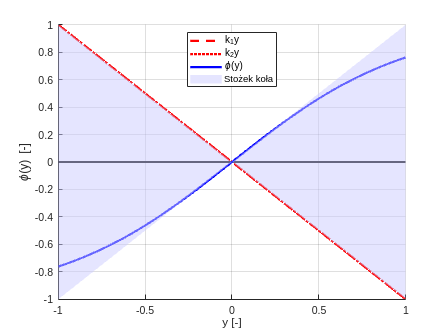

k1 = -1;
k2 = 1;

if k1 > k2
    fprintf("BŁąd: k1 > k2");
    return;
end

y = -1:0.01:1;
fi_plot = fi_a(y);
k1_plot = k1 * y;
k2_plot = k2 * y;
zero_plot = zeros(size(k1_plot));

figure();
grid on;
hold on;
xlabel("y [-]");
ylabel("\phi(y) [-]");
legend("show", "Location", "best");
plot(y, k1_plot, "r--", "LineWidth", 2, "DisplayName", "k_1y");
plot(y, k1_plot, "r:", "LineWidth", 2, "DisplayName", "k_2y");
plot(y, zero_plot, "k", "LineWidth", 2, "HandleVisibility", "off");
plot(y, fi_plot, "b", "LineWidth", 2, "DisplayName", "\phi(y)");
% Zaznacz obszar Popova
fill([y fliplr(y)], [k1_plot fliplr(k2_plot)], ...
     [0.8 0.8 1], 'EdgeColor', 'none', 'FaceAlpha', 0.5, "DisplayName", "Stożek koła");

Sprawdzenie czy istnieje regulator liniowy stabilizujący część liniową:

[r, krl] = rlocus(G_a, k1:0.01:k2);

is_stable = false;
for i = size(r, 2)
    is_stable = all(real(r(:,i)) < 0);
    if is_stable
        break;
    end
end

if ~is_stable
    fprintf("Niespełniony warunek: nie istneje liniowy regulator stabilizujący.");
    return;
end

Charakterystyka Nyquista i koło związane z sektorem:

[p, q, wout] = nyquist(G_a);

pp = squeeze(p);
qp = squeeze(q);

figure();
grid on;
hold on;
axis tight;
legend("show", "Location", "best");
xlabel("P(\omega)");
ylabel("Q(\omega)");
plot(pp, qp, "LineWidth", 2, "DisplayName", "Charakterystyka Nyquista");

if (k1 ~= 0) && (k2 ~= 0) 
    c = [-0.5*((k1+k2)/(k1*k2));0];
    r = 0.5 * abs((k1-k2)/(k1*k2));
    phi = 0:0.01:2*pi;
    circle = c + r*[cos(phi);sin(phi)];
    if k1*k2 < 0
        plot(c(1), c(2), "r+", "MarkerSize", 8, "LineWidth", 3, "DisplayName", "Środek koła");
        plot(circle(1,:), circle(2,:), "r:", "MarkerSize", 8, "LineWidth", 3, "DisplayName", "Brzeg koła");
        fill(circle(1,:), circle(2,:), "b", "FaceAlpha", 0.2, "EdgeColor", "none", "DisplayName", "Wnętrze koła");
    else
        plot(c(1), c(2), "r+", "MarkerSize", 8, "LineWidth", 3, "DisplayName", "Środek koła");
        plot(circle(1,:), circle(2,:), "r:", "MarkerSize", 8, "LineWidth", 3, "DisplayName", "Brzeg koła");
        xl = xlim;
        yl = ylim;
        Xrect = [xl(1) xl(2) xl(2) xl(1)];
        Yrect = [yl(1) yl(1) yl(2) yl(2)];
        pg_outer = polyshape(Xrect, Yrect);
        pg_hole = polyshape(circle(1,:), circle(2,:));
        pg = subtract(pg_outer, pg_hole);
        plot(pg, ...
            "FaceColor", "b", ...
            "FaceAlpha", 0.2, ...
            "EdgeColor", 'none', ...
            "DisplayName", "Wnętrze koła");
    end
elseif k2 == 0
    c = [1/k1;0];
    circle = [(1/k1)*ones(size(qp'));qp'];
    xl = xlim;
    yl = ylim;
    X = [c(1) xl(2) xl(2) c(1)];
    Y = [yl(1) yl(1) yl(2) yl(2)];
    patch(X, Y, "b", "FaceAlpha", 0.2, "EdgeColor", "none", "DisplayName", "Wnętrze koła");
    plot(c(1), c(2), "r+", "MarkerSize", 8, "LineWidth", 3, "DisplayName", "Środek koła");
    plot(circle(1,:), circle(2,:), "r:", "MarkerSize", 8, "LineWidth", 3, "DisplayName", "Brzeg koła");
elseif k1 == 0
    c = [1/k2;0];
    circle = [(1/k2)*ones(size(qp'));qp'];
    xl = xlim;
    yl = ylim;
    X = [c(1) xl(1) xl(1) c(1)];
    Y = [yl(1) yl(1) yl(2) yl(2)];
    patch(X, Y, "b", "FaceAlpha", 0.2, "EdgeColor", "none", "DisplayName", "Wnętrze koła");
    plot(c(1), c(2), "r+", "MarkerSize", 8, "LineWidth", 3, "DisplayName", "Środek koła");
    plot(circle(1,:), circle(2,:), "r:", "MarkerSize", 8, "LineWidth", 3, "DisplayName", "Brzeg koła");
end

Przebiegi układu sterowania:

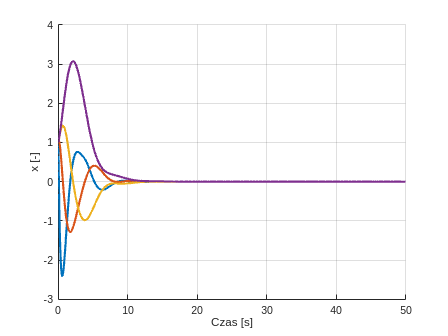

[A, B, C, ~] = tf2ss(G.Numerator{1}, G.Denominator{1});

% funkcja do ode45
system = @(t,x)(A*x - B*fi(C*x));

[t, y] = ode45(system, [0, 50], ones(size(B)));

figure();
grid on;
hold on;
xlabel("Czas [s]");
ylabel("x [-]");
plot(t, y, "LineWidth", 2);